# Denso HR Robot - II

Aadiv Shah - RBE 501

In this file the dynamics of the DENSO HR Robot are evaluated. Taking into account several factors like link mass, inertia and payload mass, the joint velocities and joint torques are calculated as well as the end effector force required to lift an object of certain mass.

% initialise matlab 
clc
close all
clear 

## Robot Parameters

In this block all the robot parameters are defined, the DH Table is used to find the relations for forward kinematics. 

To solve for dynamics, the robot object has a data format of column. To make the code computationally efficient, large values of the link lenghts have been scaled down. This allows for faster computation.

l1=205;
l11=100;
l2=275;
l4=100;

%DH Table : Given
dhparams=[l1 0 l11 0;
             l2 pi*1000 0 0;
             0 0 0 0;
             0 0 l4 0] / 1000;

robot = rigidBodyTree;

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');

setFixedTransform(jnt1,dhparams(1,:),'dh');
body1.Joint = jnt1;

addBody(robot,body1,'base')
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','prismatic'); % prismatic joint
jnt3.PositionLimits = [-2 2];
jnt3.HomePosition = 0;
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');


setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');


body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;


addBody(robot,body2,'body1')
addBody(robot,body3,'body2')
addBody(robot,body4,'body3')

% initialise gravity in the negative Z direction
robot.Gravity = [0 0 -9.81];
robot.DataFormat = 'column';

% show the final robot
showdetails(robot)

--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


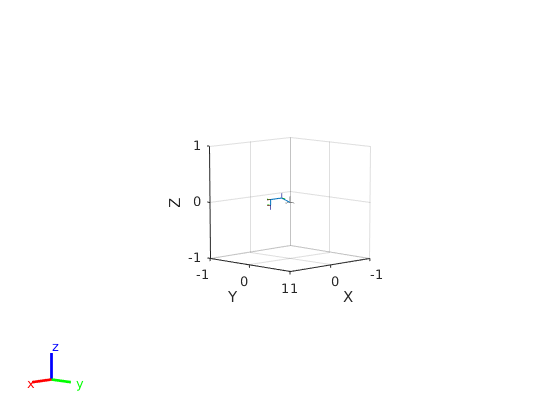

show(robot);
axis([-1 1 -1 1 -1 1])

com = centerOfMass(robot); % plot the center of mass

## Trajectory Planning

In this block, the predefined path for the DENSO HR robot is calculated. The aim is to mimic the motion of the video given. Here I make the end effector trace paths such that moves from side to side and the end effector moves up and down when it has to pick up a certain load. 

The joint positions are calculated by inverse kinematics for a specific pose and orientation of the robot. I have defined some modular functions that will help in the making the trajectory planning simpler namely

- pathCircle() - traces a circular path of given radius from a center

- pathDown() - moves the end effector *down *to pick up the object

All the subpaths are appended into a single matrix that contains all the points of the trajectory. The initial guess for the inverse kinematics is estimated at the home position. Finally the joint torque matrix is initialised with all zeros

% forward semi circle 1
t = (0:1:10)'; % Time
center = [0 0 -0.5];
radius = 0.4;
theta = t*(2*pi/t(end))/2;
z = zeros(size(theta));
arc1 = pathCircle(center,radius,theta);

% down 1 at semicircle 1
down1 = pathDown(0.5,1,arc1(end,1),arc1(end,2));
% up1 at semicircle 1
up1 = flip(down1,1);

% backward semicircle 1
arcBack1 = flip(arc1,1);

% down 1 at semicircle 1
down11 = pathDown(0.5,1,arcBack1(end,1),arcBack1(end,2));
% up1 at semicircle 1
up11 = flip(down11,1);

% forward semicircle 2
radius = 0.3;
arc2 = pathCircle(center,radius,theta);

% down 2 at semicircle 2
down2 = pathDown(0.5,1,arc2(end,1),arc2(end,2));
% up2 at semicircle 2
up2 = flip(down2,1);

% backward semicircle 1
arcBack2 = flip(arc2,1);

% down 2 at semicircle 2
down22 = pathDown(0.5,1,arcBack2(end,1),arcBack2(end,2));
% up2 at semicircle 2
up22 = flip(down22,1);


% finally after defining all the paths, they are appended into a matrix
% that contains all the waypoints of the arm in order

points = [arc1; down1; up1; arcBack1; ...
            down11; up11; down22; up22; arc2;...
                down2; up2; arcBack2];


% define the home configuration of the robot
q0 = homeConfiguration(robot);
ndof = length(q0);
qs = zeros(length(t), ndof);

ik = inverseKinematics('RigidBodyTree', robot);
weights = [0, 0, 0, 1, 1, 1];
endEffector = 'body4';

qInitial = q0; % Use home configuration as the initial guess


% initialise the jointTorq matrix
jointTorq = zeros(length(points),4);

## Inverse Kinematics

In this block the inverse kinematics for the robot is applied that allows us to identify the robot configuration for every point on the trajectory. 

for i = 1:length(points)
    % Solve for the configuration satisfying the desired end effector position
    point = points(i,:);
    qSol = ik(endEffector,trvec2tform(point),weights,qInitial);
    
    % Store the configuration
    qs(i,:) = qSol;
    
    % Start from prior solution
    qInitial = qSol;
end

## Inverse Dynamics

In this block, the joint torques at every trajectory point are calculated by using the robot confifguration and joint velocity information.

Here we may compare two seperate results, one where the joint velocity is constant and one where the joint velocity is dependent on the joint positions. The figures for both are shown. 

% here two cases are tested - variable velocity and constant velocity

% variable velocity is calculated by taking the difference of the joints at every
% point

% qdot = diff(qs);
% for i = 1:length(qdot)
%     jointTorq(i,:) = inverseDynamics(robot,qs(i,:)',qdot(i,:)');
% end
% 
% % plot
% figure
% subplot(2,2,1)
% plot(jointTorq(:,1));
% title("Joint 1")
% subplot(2,2,2)
% plot(jointTorq(:,2)); 
% title("Joint 2")
% subplot(2,2,3)
% plot(jointTorq(:,3)); 
% title("Joint 3")
% subplot(2,2,4)
% plot(jointTorq(:,4));
% title("Joint 4")
% 
% 
% % a constant velocity is taken for all further torque calculations
% qdot = 0.5*ones(length(qs),4);
% for i = 1:length(qdot)
%     jointTorq(i,:) = inverseDynamics(robot,qs(i,:)',qdot(i,:)');
% end
% 
% figure
% subplot(2,2,1)
% plot(jointTorq(:,1));
% title("Joint 1")
% subplot(2,2,2)
% plot(jointTorq(:,2)); 
% title("Joint 2")
% subplot(2,2,3)
% plot(jointTorq(:,3)); 
% title("Joint 3")
% subplot(2,2,4)
% plot(jointTorq(:,4));
% title("Joint 4")

## Force Calculation

At the point where the robot picks up the object, the total force needs to be calculated. This is done by defining a wrench vector with a force of -9.81 N in the negative Z direction. 

Finally using inverse dynamics, the total force that needs to be applied by the *prismatic *joint is calculated (assuming the mass of all the links in the system are the same at 1kg)

As expected we see the total force when the object is just lifted from the ground is equal to weight of the link +  weight of the link (end effector) + weight of the object = 9.81 * 3 = 29.44

% % define wrench vector 
% wrench = [0 0 0 0 10 -9.81];
% 
% % calculate external force
% fext = externalForce(robot,'body4',wrench);
% 
% % calculate the force at the prismatic joint just when the object is lifted
% prismaticForce = inverseDynamics(robot,qs(length(arc1)+length(down1),:)',[],[],fext);

## Force Calculation

In this block of code the external force is applied to the system at the prismatic joint in the negative Z direction. Using the inverseDynamics function, the external force and torque for each waypoint is calculated and plotted. Here the mass of the links and their inertias are taken from the robot model (rigid body tree)

% % initialise the prismatic force matrix that contains all the torque/force
% % values for the robot
% 
% prismaticForce = zeros(4,length(qs));
% for i=1:length(qs)
%     % fext is 0 for the first arc and non zero for the rest
%     if(i < length(arc1)+length(down1))
%         fext = zeros(6,4);
%     elseif(i > length(arc1)+length(down1)+length(up1)+length(arcBack1)+ ...
%             length(down11)+length(up11)+length(down22)+length(up22)+length(arc2)+...
%                 length(down2))
%         fext = zeros(6,4);
%     else
%         fext = externalForce(robot,'body4',wrench);
%     end
%     prismaticForce(:,i) = inverseDynamics(robot,qs(i,:)',[],[],fext);
% end
% 
% % Plot of the joint torques at every point on the trajectory
% % joint 3 - prismatic joint is equal to load + end effector weight when the load is on the end effector
% % and it is equal to the wieght of the end effector when the load is absent
% figure
% subplot(2,2,1)
% plot(prismaticForce(1,:));
% title("Joint 1")
% subplot(2,2,2)
% plot(prismaticForce(2,:)); 
% title("Joint 2")
% subplot(2,2,3)
% plot(prismaticForce(3,:)); 
% title("Joint 3")
% subplot(2,2,4)
% plot(prismaticForce(4,:));
% title("Joint 4")

## End Effector Velocity Calculation

In this block the velocity of the end effector is calculated. At first the jacobian matrix is calculated which is used to compute the end effector velocity using the joint angles at each point.

% geoJacob = geometricJacobian(robot,robot.homeConfiguration,'body4')
% 
% 
% % velocity of end effector at every point on the trajectory 
% % [vx vy vz wx wy wz]
% 
% figure
% vel = geoJacob * qs';
% plot(sqrt(vel(1,:).^2 + vel(2,:).^2 + vel(3,:).^2))
% title("Velocity of End Effector")

## Plots - Robot + Trajectories

Figure opens in a new window with the animation

stlData_fin = stlread("stl/1tooth_mesh2.STL");

points_fin= stlData_fin.Points;
ptCloud_fin = pointCloud(points_fin);


% Final tooth inside the considered tooth
% figure
% pcshow(ptCloudB.Location);
% hold on;
% pcshow(ptCloud_fin);
% hold off;

%Transformation (shrink and move)
Sx = 0.011;
Sy = 0.011;
Sz = 0.011;


tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);
% ptCloud_3t = pctransform(ptCloudB,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);
rot = [1 0 0; 0 1 0; 0 0 1];
zCoord = -0.5;
trans = [0.55 0.04 zCoord];
tform = rigid3d(rot,trans);
% ptCloud_3t = pctransform(ptCloud_3t,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);

figure
pcshow(ptCloud_fin); hold on;
xlabel('X'); ylabel('Y'); zlabel('Z')

% figure
show(robot,qs(1,:)');
view([1 1 1])
ax = gca;
ax.Projection = 'perspective';
hold on
plot3(points(:,1),points(:,2),points(:,3),'k')

collisionObj = collisionCylinder(0.05,0.25);

for i = 1:robot.NumBodies
    addCollision(robot.Bodies{i},collisionObj)
end
% figure
% show(robot,'Collisions','on','Visuals','off');

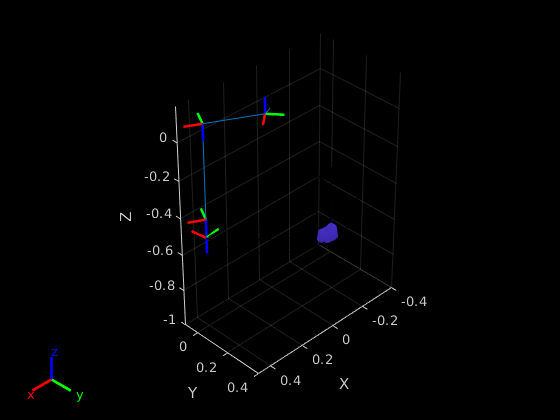

close all
figure
hold on
grid on
h = animatedline;
m = collisionMesh(ptCloud_fin.Location);

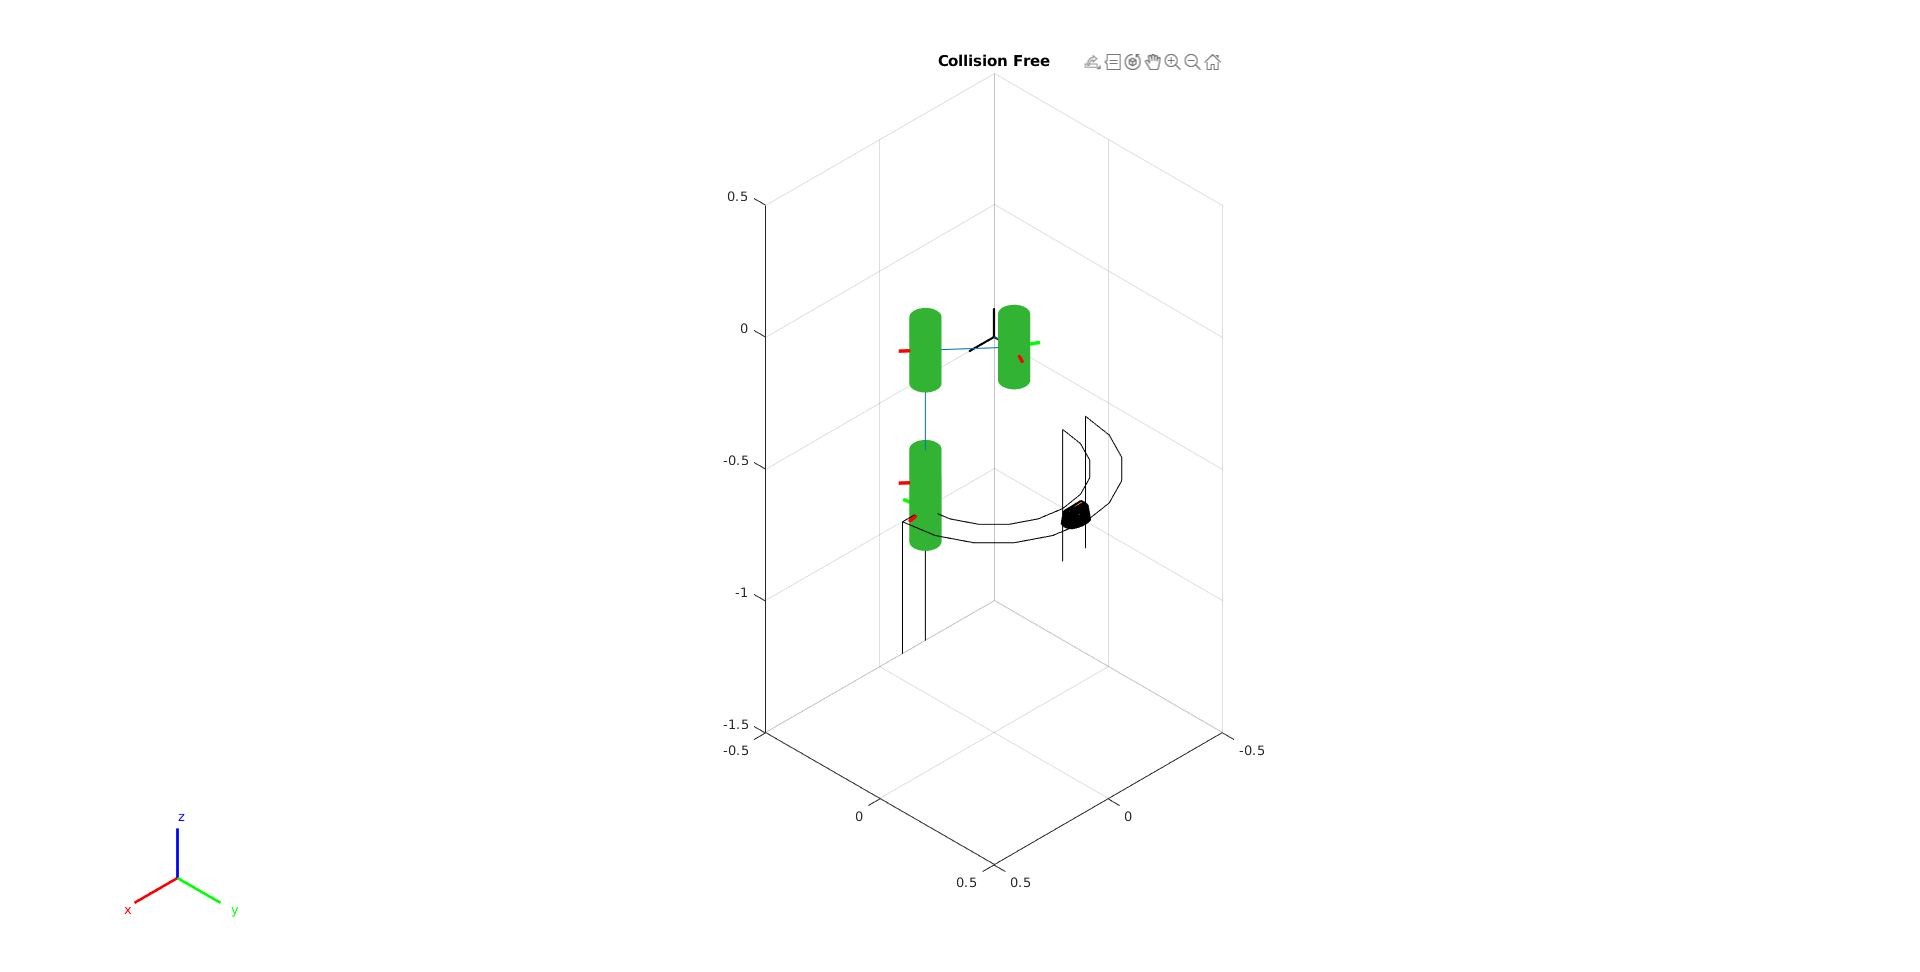




for i = 1:length(points)
    show(m)
    show(robot,qs(i,:)','PreservePlot',false,'Collisions','on');
    isColliding = checkCollision(robot,qs(i,:)',{m});
    if isColliding(2)
        title('Collision Detected')
    else
        title("Collision Free")
    end
    view([1 1 1]);
    axis equal;
    axis([-0.5 0.5 -0.5 0.5 -1.5 0.5])
    addpoints(h,points(i,1),points(i,2),points(i,3));
    drawnow
    pause(0.1)
end


## User Defined Funcitons

pathCircle()

pathDown()

function [arc] = pathCircle(center,radius,theta)
    
z = -(center(3))*zeros(size(theta));
arc = center + [radius*cos(theta) radius*sin(theta) z];

end


function [lineDown] = pathDown(start,endPath,x,y)

down = start:(endPath-start)/5:endPath;

lineDown = [x*ones(length(down),1)...
                y*ones(length(down),1)...
                -down'];
end